w_ASDT = load('/Users/domo/Documents/MATLAB/Graph_theory/ranged_consistency_thresholding_longitudinalv1/ASD_w_longitudinalv1_consistency.mat');
w_ASD_tensor = w_ASDT.tensor_ASD;
w_NTT = load('/Users/domo/Documents/MATLAB/Graph_theory/ranged_consistency_thresholding_longitudinalv1/NT_w_longitudinalv1_consistency.mat');
w_NT_tensor = w_NTT.tensor_NT;
ASDw = w_ASD_tensor(:,:,:,71);
NTw = w_NT_tensor(:,:,:,71);


ASD = [10001, 10002, 10003, 10004, 10005, 10008, 10010, 10020, 10021, 10050, 10059, 10061, 10069, 10077, 10079, 10090, 10091, 10092, 10093, 10096,...
    10101, 10115, 10119, 10124, 11001, 11003, 11007, 11014, 11019, 11031, 11038, 11044, 11054, 11059, 11061];
NT = [10009, 10013, 10014, 10015, 10016, 10017, 10019, 10036, 10044, 10052, 10057, 10076, 10086, 10088, 10103, 10106, 10112, 10113, 11006,...
    11008, 11009, 11013, 11016, 11021, 11027, 11028, 11032, 11039, 11041, 11074];

beta1s_ASD_table = readtable('/Users/domo/Documents/MATLAB/Data/beta1s_ASD.xlsx');
beta1s_NT_table = readtable('/Users/domo/Documents/MATLAB/Data/beta1s_NT.xlsx');

beta1s_ASD = table2array(beta1s_ASD_table);
beta1s_NT = table2array(beta1s_NT_table);

RM96_coords = readtable('/Users/domo/Documents/MATLAB/Data/RM96_coords.xlsx');
RM96_labels = readtable('/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx');


str_w_ASD = [];
a_w_ASD = [];

trans_w_ASD = [];

charpath_w_ASD = [];
efficiency_w_ASD = [];
ecc_w_ASD = [];
rad_w_ASD = [];
diam_w_ASD = [];
bc_w_ASD = [];

mod_w_ASD = [];

swp_w_ASD = [];

beta1s_filt_ASD = [];
ASD_filt = [];

for i = 1:length(ASD)
    if ismember(ASD(i),beta1s_ASD(:,1))
        ind = find(ASD(i)==beta1s_ASD(:,1));
        ASD_filt = [ASD_filt; ASD(i)];
        beta1s_filt_ASD = [beta1s_filt_ASD; beta1s_ASD(ind,:)];

        %individuals w matrix
        w = ASDw(:,:,i);

        %structural classic measures
        str_w = strengths_und(w);
        str_w_ASD = [str_w_ASD; str_w];
        a_w = assortativity_wei(w,0);
        a_w_ASD = [a_w_ASD; a_w];

        [m_w,Q_w] = modularity_und(w);
        mod_w_ASD = [mod_w_ASD; Q_w];

        w_nrm = weight_conversion(w,'normalize');
        cc_w = clustering_coef_wu(w_nrm);
        trans_w = transitivity_wu(w_nrm);
        trans_w_ASD = [trans_w_ASD; trans_w];

        L_w = weight_conversion(w,'lengths');
        bc_w = betweenness_wei(L_w);
        bc_w_ASD = [bc_w_ASD; bc_w'];

        [D_w, B_w] = distance_wei(L_w);
        [cp_w,eff_w,ecc_w,rad_w,diam_w] = charpath(D_w);
        charpath_w_ASD = [charpath_w_ASD; cp_w];
        efficiency_w_ASD = [efficiency_w_ASD; eff_w];
        ecc_w_ASD = [ecc_w_ASD; ecc_w'];
        rad_w_ASD = [rad_w_ASD; rad_w];
        diam_w_ASD = [diam_w_ASD; diam_w];

        %structural swp
        C_w_brain = mean(cc_w);
        Lp_w_brain = cp_w;

        W_rand = randomize_matrix(w);
        avg_degree_w = mean(degrees_und(w));
        r_w = ceil(avg_degree_w/2);
        W_latt = regular_matrix_generator(w,r_w);

        Wrand_nrm = weight_conversion(W_rand,'normalize');
        Wlatt_nrm = weight_conversion(W_latt,'normalize');

        cc_w_rand = clustering_coef_wu(Wrand_nrm);
        cc_w_latt = clustering_coef_wu(Wlatt_nrm);
        C_w_rand = mean(cc_w_rand);
        C_w_latt = mean(cc_w_latt);

        deltaC_w = (C_w_latt-C_w_brain)/(C_w_latt-C_w_rand);

        L_w_rand = weight_conversion(W_rand,'lengths');
        L_w_latt = weight_conversion(W_latt,'lengths');
        [D_w_rand, B_w_rand] = distance_wei(L_w_rand);
        [D_w_latt, B_w_latt] = distance_wei(L_w_latt);
        Lp_w_rand = charpath(D_w_rand);
        Lp_w_latt = charpath(D_w_latt);
    
        deltaL_w = (Lp_w_brain-Lp_w_rand)/(Lp_w_latt-Lp_w_rand);
    
        phi = 1 - sqrt((deltaC_w^2+deltaL_w^2)/2);
    
        swp_w_ASD = [swp_w_ASD; phi];
    end
end

str_w_NT = [];
a_w_NT = [];

trans_w_NT = [];

charpath_w_NT = [];
efficiency_w_NT = [];
ecc_w_NT = [];
rad_w_NT = [];
diam_w_NT = [];
bc_w_NT = [];

mod_w_NT = [];

swp_w_NT = [];


beta1s_filt_NT = [];
NT_filt = [];

for i = 1:length(NT)
    if ismember(NT(i),beta1s_NT(:,1))
        ind = find(NT(i)==beta1s_NT(:,1));
        NT_filt = [NT_filt; NT(i)];
        beta1s_filt_NT = [beta1s_filt_NT; beta1s_NT(ind,:)];

        w = NTw(:,:,i);

        str_w = strengths_und(w);
        str_w_NT = [str_w_NT; str_w];
        a_w = assortativity_wei(w,0);
        a_w_NT = [a_w_NT; a_w];

        [m_w,Q_w] = modularity_und(w);
        mod_w_NT = [mod_w_NT; Q_w];

        w_nrm = weight_conversion(w,'normalize');
        cc_w = clustering_coef_wu(w_nrm);
        trans_w = transitivity_wu(w_nrm);
        trans_w_NT = [trans_w_NT; trans_w];

        L_w = weight_conversion(w,'lengths');
        bc_w = betweenness_wei(L_w);
        bc_w_NT = [bc_w_NT; bc_w'];

        [D_w, B_w] = distance_wei(L_w);
        [cp_w,eff_w,ecc_w,rad_w,diam_w] = charpath(D_w);
        charpath_w_NT = [charpath_w_NT; cp_w];
        efficiency_w_NT = [efficiency_w_NT; eff_w];
        ecc_w_NT = [ecc_w_NT; ecc_w'];
        rad_w_NT = [rad_w_NT; rad_w];
        diam_w_NT = [diam_w_NT; diam_w];

        %structural swp
        C_w_brain = mean(cc_w);
        Lp_w_brain = cp_w;

        W_rand = randomize_matrix(w);
        avg_degree_w = mean(degrees_und(w));
        r_w = ceil(avg_degree_w/2);
        W_latt = regular_matrix_generator(w,r_w);

        Wrand_nrm = weight_conversion(W_rand,'normalize');
        Wlatt_nrm = weight_conversion(W_latt,'normalize');

        cc_w_rand = clustering_coef_wu(Wrand_nrm);
        cc_w_latt = clustering_coef_wu(Wlatt_nrm);
        C_w_rand = mean(cc_w_rand);
        C_w_latt = mean(cc_w_latt);

        deltaC_w = (C_w_latt-C_w_brain)/(C_w_latt-C_w_rand);

        L_w_rand = weight_conversion(W_rand,'lengths');
        L_w_latt = weight_conversion(W_latt,'lengths');
        [D_w_rand, B_w_rand] = distance_wei(L_w_rand);
        [D_w_latt, B_w_latt] = distance_wei(L_w_latt);
        Lp_w_rand = charpath(D_w_rand);
        Lp_w_latt = charpath(D_w_latt);
    
        deltaL_w = (Lp_w_brain-Lp_w_rand)/(Lp_w_latt-Lp_w_rand);
    
        phi = 1 - sqrt((deltaC_w^2+deltaL_w^2)/2);
    
        swp_w_NT = [swp_w_NT; phi];
    end
end

%%We look at group differences in structural strength, eccentricity,
%%betweenness centrality and global measures

AVLTA7_ASD = beta1s_filt_ASD(:,6);
AVLTA7_NT = beta1s_filt_NT(:,6);


%%information for pls_analysis code
num_subj = [33;29];
num_cond = 1;
option.stacked_behavdata = [AVLTA7_ASD;AVLTA7_NT];
option.method = 3; %behavioral PLS
option.num_perm = 10000;
option.num_boot = 1000;

%%structural strength
str_lst{1} = str_w_ASD;
str_lst{2} = str_w_NT;
result_str = pls_analysis(str_lst,num_subj,num_cond,option);

Stacking datamat from group: 1 2
 
Calculating Covariance / Correlation data ...
Calculating LVs ...
Calculating Scores ...

Making resampling matrix for permutation ...
Working on 10000 permutations: 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17
 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41
 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65
 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89
 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110
 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128
 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146
 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164
 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182
 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200
 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218
 219 220 221 222 223 224 

result_str.perm_result.sprob

ans =     0.0143
    0.6195


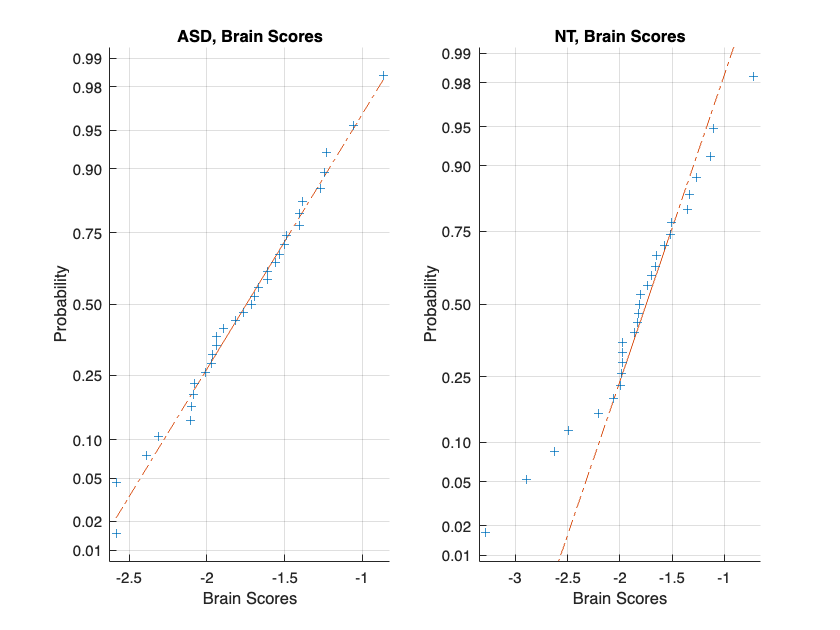

%%Significant latent variable, LV1
%%We identify if there is a significant difference between brain scores
%%within each group
%%Check for Gaussian, for t-testing
lv=1;
figure;
subplot(1,2,1)
normplot(result_str.usc(1:33,lv))
title('ASD, Brain Scores')
xlabel('Brain Scores')
subplot(1,2,2)
normplot(result_str.usc(34:62,lv))
title('NT, Brain Scores')
xlabel('Brain Scores')

[h,p] = ttest2(result_str.usc(1:33,lv),result_str.usc(34:62,lv))

h = 0

p = 0.5666

%%no significant difference in brain scores

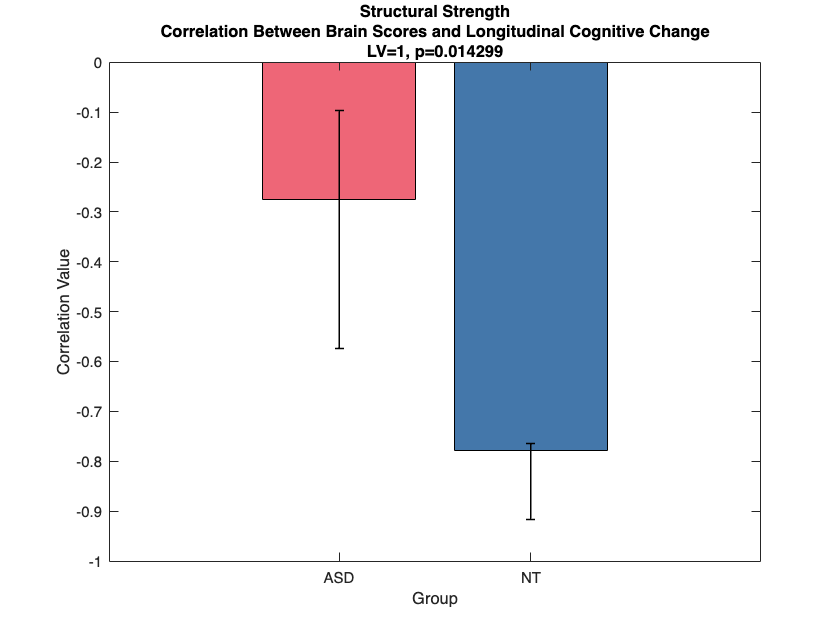

%%we visualize the correlation between
%%the brain scores and the lognitudinal cognitive change 

figure;
b = bar(1:2, result_str.lvcorrs(:, lv));
b.FaceColor = 'flat';
colors = [238 102 119; 68 119 170]/255;
b.CData = colors;
hold on;
% ylim([-1, 0.5]);

lower = result_str.boot_result.orig_corr(:, lv) - result_str.boot_result.llcorr(:, lv);
upper = result_str.boot_result.ulcorr(:, lv) - result_str.boot_result.orig_corr(:, lv);
er = errorbar(1:2, result_str.lvcorrs(:, lv), lower, upper);
er.Color = [0 0 0];
er.LineStyle = 'none';
er.LineWidth = 1;

xlabel('Group');
xticklabels({'ASD', 'NT'});
ylabel('Correlation Value');
hold off
title(["Structural Strength", "Correlation Between Brain Scores and Longitudinal Cognitive Change", "LV="+num2str(lv)+", p="+num2str(result_str.perm_result.sprob(lv))]);

%%identify significant contributing regions from bootstrapping analysis and
%%create nodes file for BrainNet viewing
thresh = 2;
bsr_str = result_str.boot_result.compare_u(:,lv);
sig_bsr_str = [];
for i = 1:96
    if bsr_str(i) > thresh | bsr_str(i) < -thresh
        sig_bsr_str = [sig_bsr_str; i];
        disp(RM96_labels{i,'Labels'})
        disp(bsr_str(i))
    end
end

    {'RM-PFCom_R'}



   -2.1028



    {'RM-HC_R'}



   -2.9312



    {'RM-CCr_R'}



    2.1240



    {'RM-PFCdm_R'}



    2.8058



    {'RM-PFCdl_R'}



    4.3276



    {'TM-F_R'}



   -2.5541



    {'TM-T_R'}



   -2.4886



    {'RM-PMCvl_L'}



    2.6385



    {'RM-HC_L'}



   -2.9900



    {'RM-PCm_L'}



   -2.0300



    {'RM-PFCdm_L'}



    2.0240



    {'TM-F_L'}



   -2.2020



    {'TM-OP_L'}



   -2.3831



    {'BG-Cd_L'}



   -2.0487



    {'BG-Pa_L'}



   -3.7686



str_nodes_table = table();
str_nodes_table.x = RM96_coords{sig_bsr_str,'X'};
str_nodes_table.y = RM96_coords{sig_bsr_str,'Y'};
str_nodes_table.z = RM96_coords{sig_bsr_str,'Z'};
str_nodes_table.color = bsr_str(sig_bsr_str);
str_nodes_table.size = ones(length(sig_bsr_str),1);
str_nodes_table.label = RM96_labels{sig_bsr_str,'Labels'};
writetable(str_nodes_table,'bPLS_sig_str_nodes_table.txt','Delimiter','\t','WriteVariableNames',false)

%%structural eccentricity
ecc_lst{1} = ecc_w_ASD;
ecc_lst{2} = ecc_w_NT;
result_ecc = pls_analysis(ecc_lst,num_subj,num_cond,option);

Stacking datamat from group: 1 2
 
Calculating Covariance / Correlation data ...
Calculating LVs ...
Calculating Scores ...

Making resampling matrix for permutation ...
Working on 10000 permutations: 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17
 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41
 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65
 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89
 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110
 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128
 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146
 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164
 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182
 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200
 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218
 219 220 221 222 223 224 

result_ecc.perm_result.sprob

ans =     0.0205
    0.2593


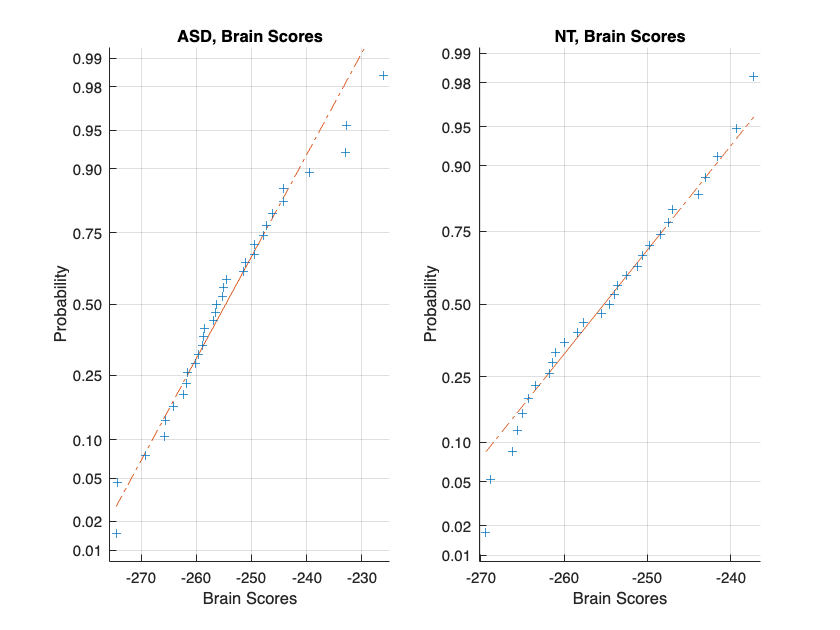

%%Significant latent variable, LV1
%%We identify if there is a significant difference between brain scores
%%within each group
%%Check for Gaussian, for t-testing
lv=1;
figure;
subplot(1,2,1)
normplot(result_ecc.usc(1:33,lv))
title('ASD, Brain Scores')
xlabel('Brain Scores')
subplot(1,2,2)
normplot(result_ecc.usc(34:62,lv))
title('NT, Brain Scores')
xlabel('Brain Scores')

[h,p] = ttest2(result_ecc.usc(1:33,lv),result_ecc.usc(34:62,lv))

h = 0

p = 0.8134

%%no significant difference in brain scores

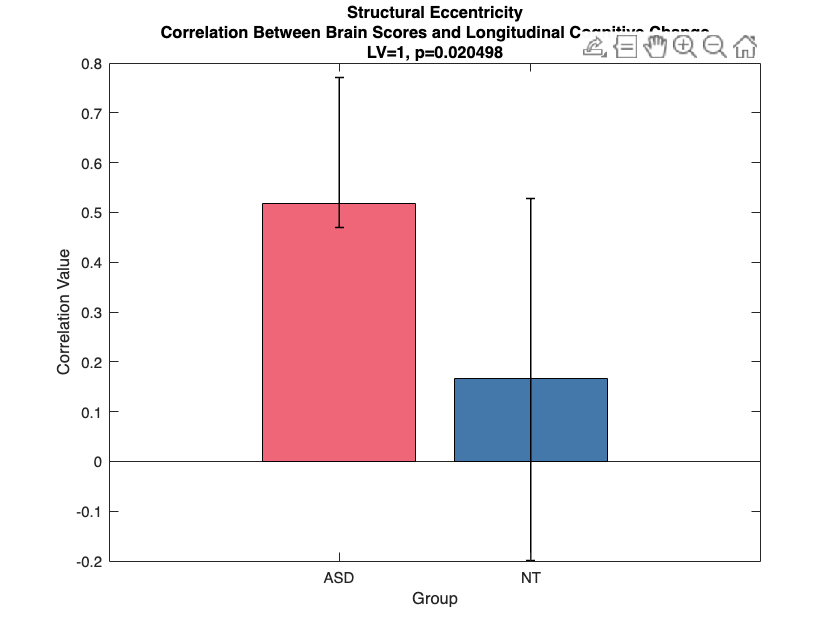

%%we visualize the correlation between
%%the brain scores and the lognitudinal cognitive change 

figure;
b = bar(1:2, result_ecc.lvcorrs(:, lv));
b.FaceColor = 'flat';
colors = [238 102 119; 68 119 170]/255;
b.CData = colors;
hold on;
% ylim([-1, 0.5]);

lower = result_ecc.boot_result.orig_corr(:, lv) - result_ecc.boot_result.llcorr(:, lv);
upper = result_ecc.boot_result.ulcorr(:, lv) - result_ecc.boot_result.orig_corr(:, lv);
er = errorbar(1:2, result_ecc.lvcorrs(:, lv), lower, upper);
er.Color = [0 0 0];
er.LineStyle = 'none';
er.LineWidth = 1;

xlabel('Group');
xticklabels({'ASD', 'NT'});
ylabel('Correlation Value');
hold off
title(["Structural Eccentricity", "Correlation Between Brain Scores and Longitudinal Cognitive Change", "LV="+num2str(lv)+", p="+num2str(result_ecc.perm_result.sprob(lv))]);

%%identify significant contributing regions from bootstrapping analysis and
%%create nodes file for BrainNet viewing
thresh = 2;
bsr_ecc = result_ecc.boot_result.compare_u(:,lv);
sig_bsr_ecc = [];
for i = 1:96
    if bsr_ecc(i) > thresh | bsr_ecc(i) < -thresh
        sig_bsr_ecc = [sig_bsr_ecc; i];
        disp(RM96_labels{i,'Labels'})
        disp(bsr_ecc(i))
    end
end

    {'RM-TCi_R'}



   -3.2210



    {'RM-PHC_R'}



   -2.7551



    {'RM-PMCvl_R'}



   -2.2843



    {'RM-VACv_R'}



   -3.5280



    {'RM-HC_R'}



   -2.1068



    {'RM-V2_R'}



   -2.3892



    {'RM-TCv_R'}



   -4.2304



    {'RM-V1_R'}



   -2.2255



    {'RM-CCp_R'}



   -2.1111



    {'RM-S2_R'}



   -2.2625



    {'RM-PCi_R'}



   -3.3548



    {'RM-PCm_R'}



   -2.1958



    {'RM-PCip_R'}



   -4.2537



    {'RM-PCs_R'}



   -5.8026



    {'RM-PMCdl_R'}



   -2.4876



    {'TM-T_R'}



   -2.1917



    {'TM-OP_R'}



   -2.6951



    {'RM-TCpol_L'}



   -2.7279



    {'RM-Amyg_L'}



   -2.3979



    {'RM-PFCoi_L'}



   -2.4532



    {'RM-TCi_L'}



   -2.0782



    {'RM-PHC_L'}



   -2.2288



    {'RM-Ip_L'}



   -2.4957



    {'RM-HC_L'}



   -2.4480



    {'RM-PFCvl_L'}



   -2.1319



    {'RM-TCv_L'}



   -2.3340



    {'RM-A1_L'}



   -2.1307



    {'TM-T_L'}



   -2.2892



    {'BG-Cd_L'}



   -2.0022



    {'BG-Pu_L'}



   -2.9514



    {'BG-Pa_L'}



   -2.3787



    {'BG-Acc_L'}



   -3.2639



ecc_nodes_table = table();
ecc_nodes_table.x = RM96_coords{sig_bsr_ecc,'X'};
ecc_nodes_table.y = RM96_coords{sig_bsr_ecc,'Y'};
ecc_nodes_table.z = RM96_coords{sig_bsr_ecc,'Z'};
ecc_nodes_table.color = bsr_ecc(sig_bsr_ecc);
ecc_nodes_table.size = ones(length(sig_bsr_ecc),1);
ecc_nodes_table.label = RM96_labels{sig_bsr_ecc,'Labels'};
writetable(ecc_nodes_table,'bPLS_sig_ecc_nodes_table.txt','Delimiter','\t','WriteVariableNames',false)

%%structural betweenness centrality
bc_lst{1} = bc_w_ASD;
bc_lst{2} = bc_w_NT;
result_bc = pls_analysis(bc_lst,num_subj,num_cond,option);

Stacking datamat from group: 1 2
 
Calculating Covariance / Correlation data ...
Calculating LVs ...
Calculating Scores ...

Making resampling matrix for permutation ...
Working on 10000 permutations: 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17
 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41
 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65
 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89
 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110
 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128
 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146
 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164
 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182
 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200
 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218
 219 220 221 222 223 224 

result_bc.perm_result.sprob

ans =     0.0487
    0.1179


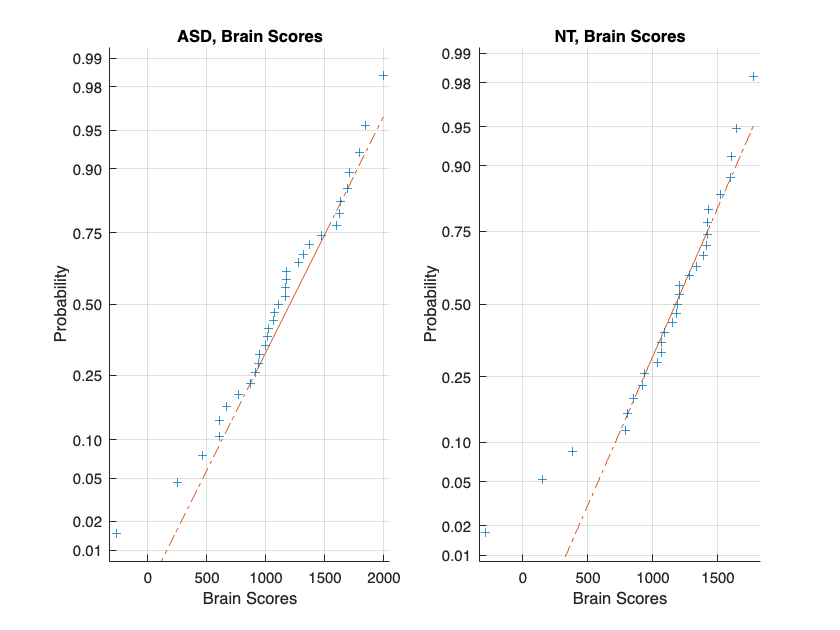

%%Significant latent variable, LV1
%%We identify if there is a significant difference between brain scores
%%within each group
%%Check for Gaussian, for t-testing
lv=1;
figure;
subplot(1,2,1)
normplot(result_bc.usc(1:33,lv))
title('ASD, Brain Scores')
xlabel('Brain Scores')
subplot(1,2,2)
normplot(result_bc.usc(34:62,lv))
title('NT, Brain Scores')
xlabel('Brain Scores')

[h,p] = ttest2(result_bc.usc(1:33,lv),result_bc.usc(34:62,lv))

h = 0

p = 0.9925

%%no significant difference in brain scores

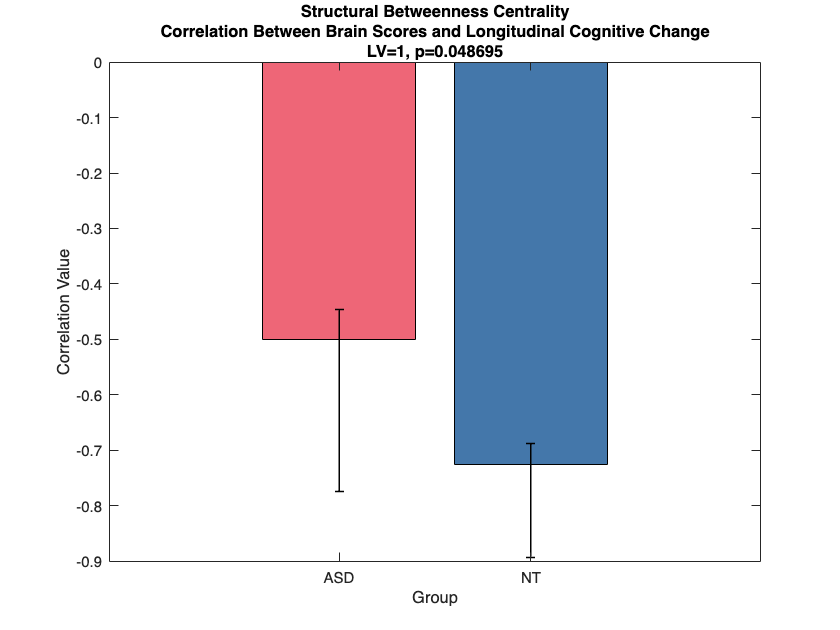

%%we visualize the correlation between
%%the brain scores and the lognitudinal cognitive change 

figure;
b = bar(1:2, result_bc.lvcorrs(:, lv));
b.FaceColor = 'flat';
colors = [238 102 119; 68 119 170]/255;
b.CData = colors;
hold on;
% ylim([-1, 0.5]);

lower = result_bc.boot_result.orig_corr(:, lv) - result_bc.boot_result.llcorr(:, lv);
upper = result_bc.boot_result.ulcorr(:, lv) - result_bc.boot_result.orig_corr(:, lv);
er = errorbar(1:2, result_bc.lvcorrs(:, lv), lower, upper);
er.Color = [0 0 0];
er.LineStyle = 'none';
er.LineWidth = 1;

xlabel('Group');
xticklabels({'ASD', 'NT'});
ylabel('Correlation Value');
hold off
title(["Structural Betweenness Centrality", "Correlation Between Brain Scores and Longitudinal Cognitive Change", "LV="+num2str(lv)+", p="+num2str(result_bc.perm_result.sprob(lv))]);

%%identify significant contributing regions from bootstrapping analysis and
%%create nodes file for BrainNet viewing
thresh = 2;
bsr_bc = result_bc.boot_result.compare_u(:,lv);
sig_bsr_bc = [];
for i = 1:96
    if bsr_bc(i) > thresh | bsr_bc(i) < -thresh
        sig_bsr_bc = [sig_bsr_bc; i];
        disp(RM96_labels{i,'Labels'})
        disp(bsr_bc(i))
    end
end

    {'RM-Amyg_R'}



   -2.8366



    {'RM-IA_R'}



   -2.0807



    {'RM-VACd_R'}



    2.1275



    {'RM-CCr_R'}



    2.3508



    {'RM-PFCdm_R'}



    3.1959



    {'TM-F_R'}



    2.1027



    {'BG-Pu_R'}



    4.0211



    {'RM-PHC_L'}



    2.0935



    {'RM-CCs_L'}



    2.7076



    {'BG-Cd_L'}



   -2.2025



    {'BG-Acc_L'}



    2.3266



bc_nodes_table = table();
bc_nodes_table.x = RM96_coords{sig_bsr_bc,'X'};
bc_nodes_table.y = RM96_coords{sig_bsr_bc,'Y'};
bc_nodes_table.z = RM96_coords{sig_bsr_bc,'Z'};
bc_nodes_table.color = bsr_bc(sig_bsr_bc);
bc_nodes_table.size = ones(length(sig_bsr_bc),1);
bc_nodes_table.label = RM96_labels{sig_bsr_bc,'Labels'};
writetable(bc_nodes_table,'bPLS_sig_bc_nodes_table.txt','Delimiter','\t','WriteVariableNames',false)

%%structural global measures
glob_w_ASD = [a_w_ASD,trans_w_ASD,charpath_w_ASD,efficiency_w_ASD,rad_w_ASD,diam_w_ASD,mod_w_ASD,swp_w_ASD];
glob_w_NT = [a_w_NT,trans_w_NT,charpath_w_NT,efficiency_w_NT,rad_w_NT,diam_w_NT,mod_w_NT,swp_w_NT];

glob_lst{1} = glob_w_ASD;
glob_lst{2} = glob_w_NT;
result_glob = pls_analysis(glob_lst,num_subj,num_cond,option);

Stacking datamat from group: 1 2
 
Calculating Covariance / Correlation data ...
Calculating LVs ...
Calculating Scores ...

Making resampling matrix for permutation ...
Working on 10000 permutations: 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17
 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41
 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65
 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89
 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110
 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128
 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146
 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164
 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182
 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200
 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218
 219 220 221 222 223 224 

result_glob.perm_result.sprob

ans =     0.0265
    0.5305


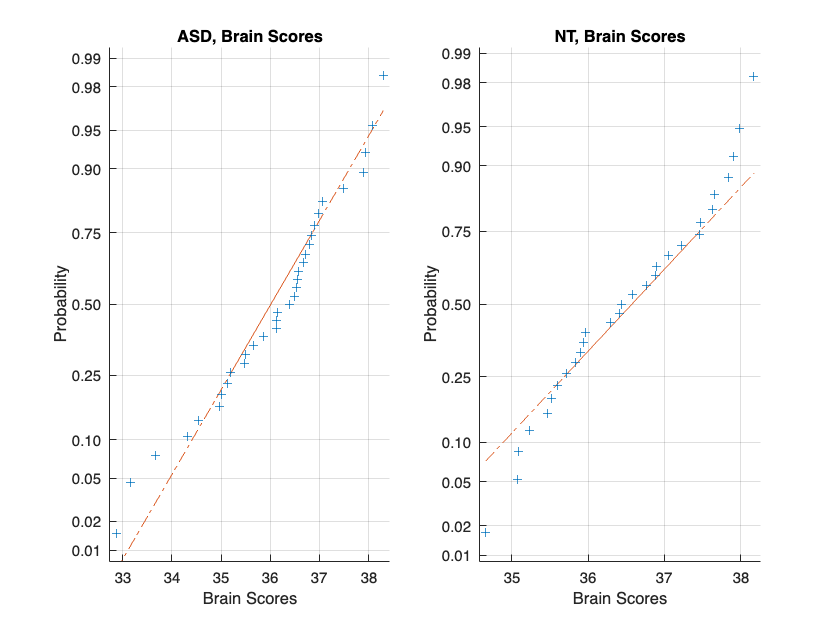

%%Significant latent variable, LV1
%%We identify if there is a significant difference between brain scores
%%within each group
%%Check for Gaussian, for t-testing
lv=1;
figure;
subplot(1,2,1)
normplot(result_glob.usc(1:33,lv))
title('ASD, Brain Scores')
xlabel('Brain Scores')
subplot(1,2,2)
normplot(result_glob.usc(34:62,lv))
title('NT, Brain Scores')
xlabel('Brain Scores')

[h,p] = ttest2(result_glob.usc(1:33,lv),result_glob.usc(34:62,lv))

h = 0

p = 0.1516

%%no significant difference in brain scores

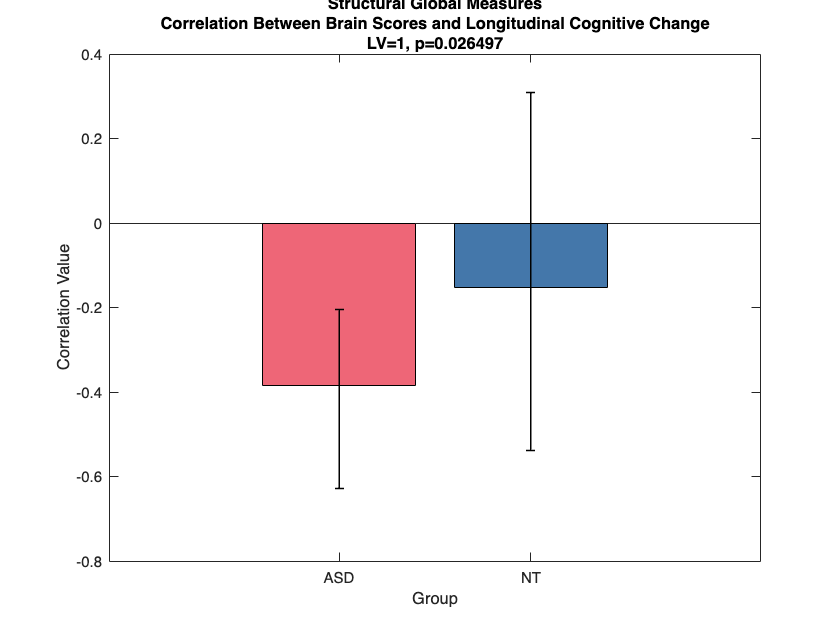

%%we visualize the correlation between
%%the brain scores and the lognitudinal cognitive change 

figure;
b = bar(1:2, result_glob.lvcorrs(:, lv));
b.FaceColor = 'flat';
colors = [238 102 119; 68 119 170]/255;
b.CData = colors;
hold on;
% ylim([-1, 0.5]);

lower = result_glob.boot_result.orig_corr(:, lv) - result_glob.boot_result.llcorr(:, lv);
upper = result_glob.boot_result.ulcorr(:, lv) - result_glob.boot_result.orig_corr(:, lv);
er = errorbar(1:2, result_glob.lvcorrs(:, lv), lower, upper);
er.Color = [0 0 0];
er.LineStyle = 'none';
er.LineWidth = 1;

xlabel('Group');
xticklabels({'ASD', 'NT'});
ylabel('Correlation Value');
hold off
title(["Structural Global Measures", "Correlation Between Brain Scores and Longitudinal Cognitive Change", "LV="+num2str(lv)+", p="+num2str(result_glob.perm_result.sprob(lv))]);

%%identify significant contributing regions from bootstrapping analysis
thresh = 2;
glob_measures = {'assortativity';'transitivity';'charpath';'efficiency';'radius';'diameter';'modularity';'small-world propensity'};
bsr_glob = result_glob.boot_result.compare_u(:,lv);
for i = 1:length(glob_measures)
    if bsr_glob(i) > thresh | bsr_glob(i) < -thresh
        disp(glob_measures{i})
        disp(bsr_glob(i))
    end
end

charpath


    3.0451



efficiency


   -2.5023



diameter


    2.3795



small-world propensity


   -2.2521

